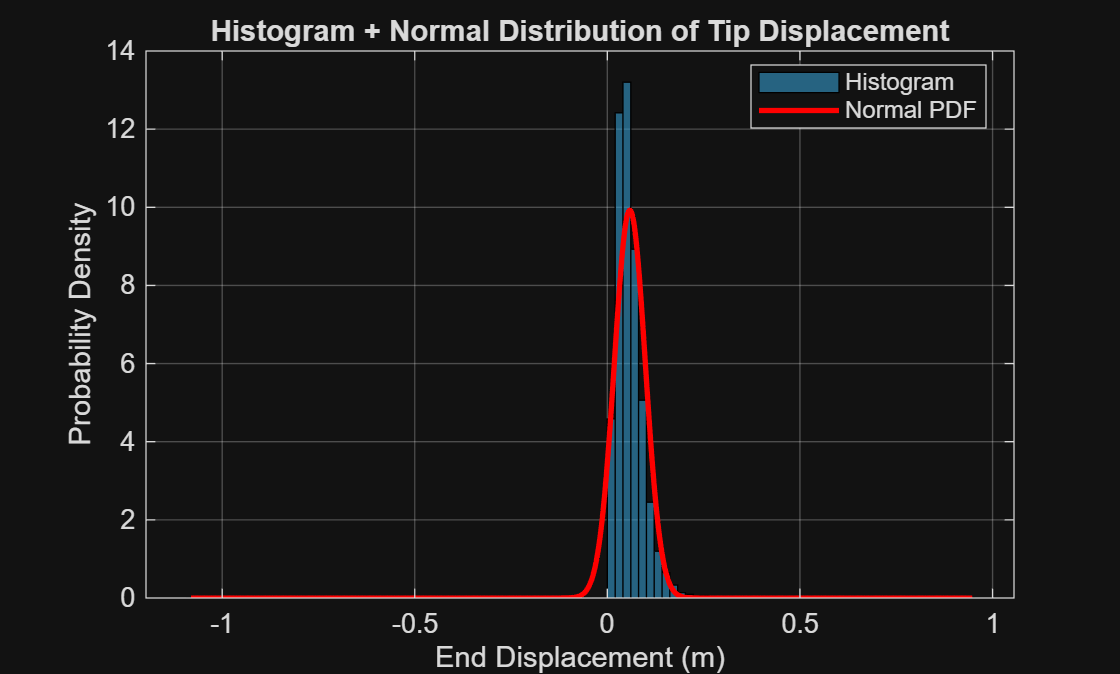

clc;
clear all;

number_of_runs = 10000;

%% Beam and FEM parameters
L_beam = 10;         
N = 5;                
Nodes = N + 1;        
partLength = L_beam / N;

% Mean EI per element
EI_mu = 210e9 * 2e-4 * ones(N,1);
EI_COV = 0.3;
EI_std = EI_COV .* EI_mu;

% Correlation matrix (30%)
corr_val = 0.3;
CorrMatrix = eye(N);
for i = 1:N
    for j = 1:N
        if abs(i - j) == 1
            CorrMatrix(i, j) = corr_val;
        elseif abs(i - j) > 1
            CorrMatrix(i, j) = 0;
        end
    end
end
D = diag(EI_std);
Cov_EI = D * CorrMatrix * D;

% Sample correlated EI
EI_samples = mvnrnd(EI_mu, Cov_EI, number_of_runs);

% Point load variation
P_mu = 20000;
P_sigma = 0.1 * P_mu;
P_samples = mvnrnd(P_mu, P_sigma, number_of_runs);

% Load location variation
x_mu = L_beam / 2;
x_sigma = 0.2 * L_beam;
x_samples = mvnrnd(x_mu, x_sigma, number_of_runs);
x_samples = min(max(x_samples, 0), L_beam);

%% DOF mapping
dof = zeros(N, 4);
for i = 1:N
    dof(i,:) = [2*i - 1, 2*i, 2*i + 1, 2*i + 2];
end

%% Monte Carlo simulation
end_displacement = zeros(number_of_runs,1);
mean_vals = zeros(number_of_runs,1);
std_vals = zeros(number_of_runs,1);

for n = 1:number_of_runs
    EI_run = EI_samples(n, :);
    P = P_samples(n);
    x_load = x_samples(n);

    element_index = min(floor(x_load / partLength) + 1, N);
    local_x = x_load - (element_index - 1) * partLength;
    xi = local_x / partLength;

    % Global stiffness matrix
    Keq = zeros(Nodes * 2);
    for i = 1:N
        Le = partLength;
        EI = EI_run(i);
        k = (EI / Le^3) * ...
            [12, 6*Le, -12, 6*Le;
             6*Le, 4*Le^2, -6*Le, 2*Le^2;
            -12, -6*Le, 12, -6*Le;
             6*Le, 2*Le^2, -6*Le, 4*Le^2];
        for j = 1:4
            for p = 1:4
                Keq(dof(i,j), dof(i,p)) = Keq(dof(i,j), dof(i,p)) + k(j,p);
            end
        end
    end

    % Equivalent point load
    N1 = 1 - 3*xi^2 + 2*xi^3;
    N2 = local_x - 2*local_x^2/partLength + local_x^3/partLength^2;
    N3 = 3*xi^2 - 2*xi^3;
    N4 = -local_x^2/partLength + local_x^3/partLength^2;
    f_local = P * [N1; N2; N3; N4];

    % Global force vector
    F = zeros(Nodes*2, 1);
    F(dof(element_index, :)) = F(dof(element_index, :)) + f_local;

    % Boundary conditions
    fixed_dofs = [1, 2];
    free_dofs = setdiff(1:Nodes*2, fixed_dofs);

    % Solve
    K_reduced = Keq(free_dofs, free_dofs);
    F_reduced = F(free_dofs);
    d = zeros(Nodes*2, 1);
    d(free_dofs) = K_reduced \ F_reduced;

    % Tip deflection (last node vertical DOF)
    end_displacement(n) = d(end - 1);

    % Running mean & std
    mean_vals(n) = mean(end_displacement(1:n));
    std_vals(n) = std(end_displacement(1:n));
end

mu_d = mean(end_displacement);
sigma_d = std(end_displacement);

% Define x-range exactly based on actual data range
x_min = min(end_displacement);
x_max = max(end_displacement);
x = linspace(x_min, x_max, 1000);
pdf_vals = normpdf(x, mu_d, sigma_d);

figure;
% Plot histogram with PDF normalization and tight bins
histogram(end_displacement, 'Normalization', 'pdf', ...
    'BinWidth', (x_max - x_min)/100, ...  % Adaptive bin width
    'FaceColor', [0.2 0.6 0.8], ...
    'EdgeColor', 'k', ...
    'DisplayName', 'Histogram');
hold on;

% Plot the fitted normal distribution
plot(x, pdf_vals, 'r-', 'LineWidth', 2, 'DisplayName', 'Normal PDF');
xlabel('End Displacement (m)');
ylabel('Probability Density');
title('Histogram + Normal Distribution of Tip Displacement');
legend('Location', 'best');
grid on;

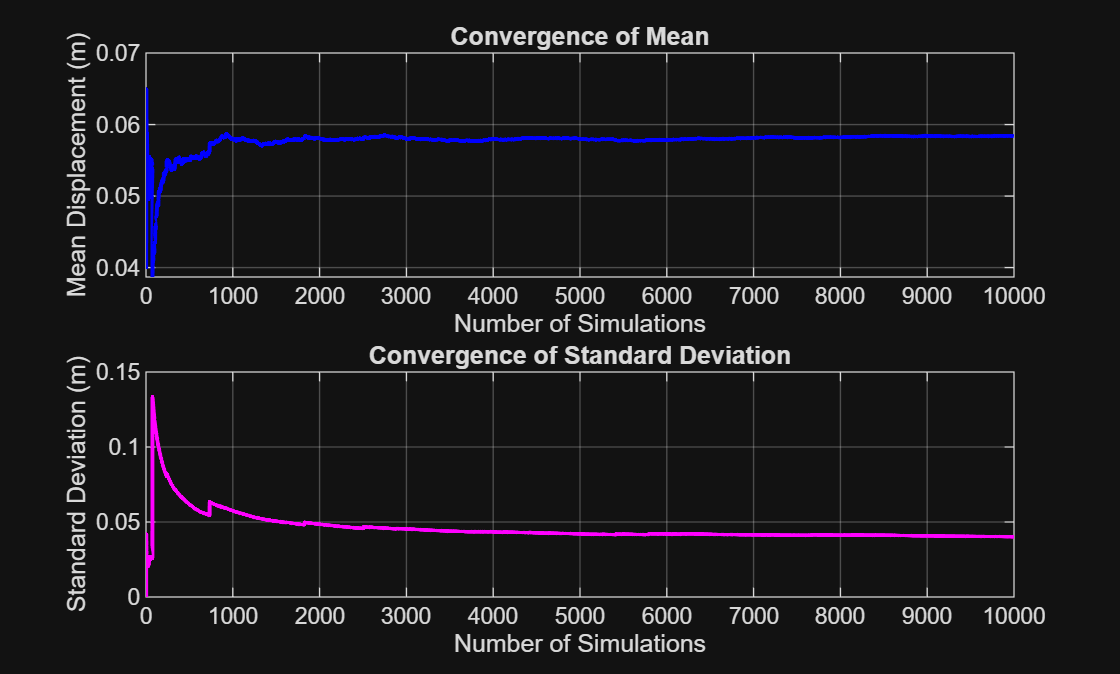



%% Plot 2: Convergence of Mean & Std Dev
figure;
subplot(2,1,1);
plot(1:number_of_runs, mean_vals, 'b', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Mean Displacement (m)');
title('Convergence of Mean');
grid on;

subplot(2,1,2);
plot(1:number_of_runs, std_vals, 'm', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Standard Deviation (m)');
title('Convergence of Standard Deviation');
grid on;


%% Output
fprintf('Final Mean of End Displacement: %.4e m\n', mu_d);

Final Mean of End Displacement: 5.8369e-02 m


fprintf('Final Std Dev of End Displacement: %.4e m\n', sigma_d);

Final Std Dev of End Displacement: 4.0171e-02 m
